p =          0         0    0.2110   -0.1230         0   90.0000   55.6860 -138.8152
         0         0    0.2104   -0.1399         0   90.0000   45.8885 -133.6220
         0         0    0.2086   -0.1567         0   90.0000   36.8929 -128.5317
         0         0    0.2057   -0.1733         0   90.0000   28.5161 -123.5088
         0         0    0.2016   -0.1897         0   90.0000   20.6260 -118.5286
         0         0    0.1964   -0.2057         0   90.0000   13.1243 -113.5723
         0         0    0.1901   -0.2214         0   90.0000    5.9350 -108.6249
         0         0    0.1827   -0.2366         0   90.0000   -1.0013 -103.6731
         0         0    0.1742   -0.2512         0   90.0000   -7.7332  -98.7049
         0         0    0.1648   -0.2652         0   90.0000  -14.3007  -93.7082
         0         0    0.1544   -0.2785         0   90.0000  -20.7383  -88.6702
         0         0    0.1431   -0.2911         0   90.0000  -27.0766  -83.5767
         0         0    

k =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


k =          0   -0.2584   -0.3000  -90.0000  -24.8026  -58.6715
         0   -0.2636   -0.3000  -90.0000  -25.1138  -57.0370
         0   -0.2677   -0.3000  -90.0000  -25.4022  -55.6976
         0   -0.2706   -0.3000  -90.0000  -25.6347  -54.7019
         0   -0.2724   -0.3000  -90.0000  -25.7853  -54.0881
         0   -0.2730   -0.3000  -90.0000  -25.8374  -53.8807
         0   -0.2608   -0.3000  -90.0000  -24.9393  -57.9228
         0   -0.2672   -0.3000  -90.0000  -25.3607  -55.8827
         0   -0.2724   -0.3000  -90.0000  -25.7823  -54.1000
         0   -0.2765   -0.3000  -90.0000  -26.1624  -52.6361
         0   -0.2794   -0.3000  -90.0000  -26.4639  -51.5456
         0   -0.2812   -0.3000  -90.0000  -26.6575  -50.8722
         0   -0.2818   -0.3000  -90.0000  -26.7243  -50.6445
         0   -0.2812   -0.3000  -90.0000  -26.6575  -50.8722
         0   -0.2540   -0.3000  -90.0000  -24.5889  -59.9786


coord =     0.3735         0   -0.2715


thetas =    0.0000 + 0.0000i -45.0000 + 0.0000i   0.0000 - 0.0000i


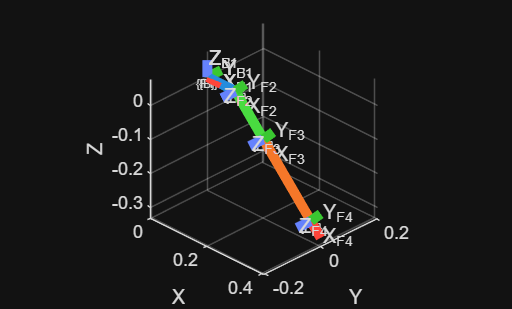

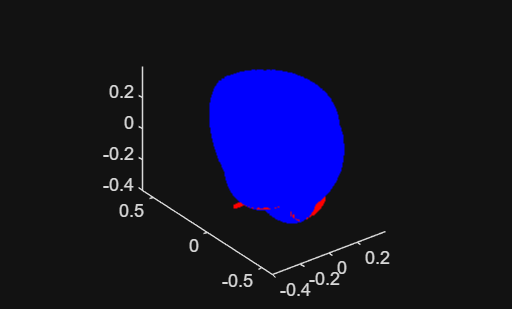

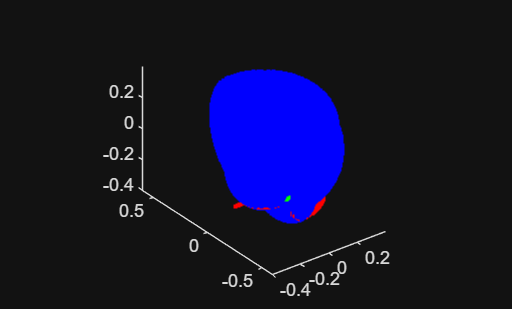

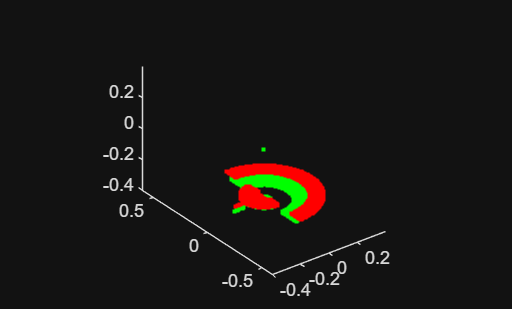

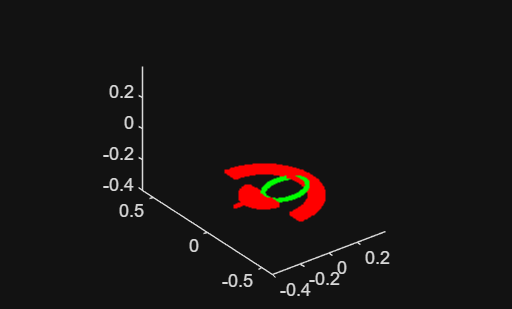

FROMLEGSTART

function FROMLEGSTART

L0 = 0.12256;
L1 = 0.1020;
L2 = 0.1420;
L3 = 0.2420;


min1=-90;
max1=90;
min2=-120;
max2=60;
min3=-60;
max3=120;

n1=91;
n2=46;
n3=46;

j1=linspace(min1,max1,n1);
j2=linspace(min2,max2,n2);
j3=linspace(min3,max3,n3);

n=1;

p=zeros(n1*n2*n3,8);
%Iterate through min-max of each joints and find x,y,z from dh notation
for a=1:n1
    for b=1:n2
        for c=1:n3

            dh = [
                0, 0, 0, j1(a);
                L1, 90, 0, j2(b);
                L2, 0, 0, j3(c);
                L3, 0, 0, 0;
                ];

            B = se3;

            F1 = TfromDH(dh(1, :));
            F2 = F1*TfromDH(dh(2, :));
            F3 = F2*TfromDH(dh(3, :));
            F4 = F3*TfromDH(dh(4, :));
            H = F4.tform;
            x = H(1,4);
            y = H(2,4);
            z = H(3,4);
            [th1,th2,th3] = ik(x,y,z);
            if a > 1 && a < n1 && b > 1 && b < n2 && c > 1 && c < n3
                continue
            end   
            zexp = -0.30;
            zexp1 = -0.33;
            [t1,t2,t3]=ik(x,y,zexp);
            [t11,t22,t33]=ik(x,y,zexp1);
            if isreal(x) && isreal(y) && isreal(z) && isreal(th1) && isreal(th2) && isreal(th3) 
                p(n, :) = [0, x, y, z, 0, th1, th2, th3];
            end
            if isreal(x) && isreal(y) && isreal(t1) && isreal(t2) && isreal(t3) && min1<=t1 && t1<=max1 && min2<=t2 && t2<=max2 && min3<=t3 && t3<=max3
                k(n, :) = [x,y,zexp, t1,t2,t3]; 
            end
            if isreal(x) && isreal(y) && isreal(t11) && isreal(t22) && isreal(t33) && min1<=t11 && t11<=max1 && min2<=t22 && t22<=max2 && min3<=t33 && t33<=max3
                m(n, :) = [x,y,zexp1, t11,t22,t33]; 
            end
            
            n = n + 1;
        end
    end
end
p
k
k = k(any(k, 2), :)

tang=30;
r=0.125;
t=-pi:0.01:pi;
cx=r*cos(t);
cy=r*sin(t);
cz=zeros(1,length(t));
cz=cz-0.31 + cos(tang)*cx-cos(tang)*cy;
%plot3(cx-0.2,cy,cz, '.g')


%plot3(p(:,2),p(:,3),p(:,4),'.b')
%plot3(p(:,2),p(:,3),p(:,4),'.b',k(:,1),k(:,2),k(:,3))

figure;
plot3(k(:,1),k(:,2),k(:,3),'.r',cx+0.15,cy,cz, '.g')
axis equal;
pbaspect([1 1 1]);

xlim([-0.4 0.4]);
ylim([-0.6 0.6]);
zlim([-0.4 0.4]);

figure;
plot3(k(:,1),k(:,2),k(:,3),'.r', m(:,1),m(:,2),m(:,3),'.g')
axis equal;
pbaspect([1 1 1]);

xlim([-0.4 0.4]);
ylim([-0.6 0.6]);
zlim([-0.4 0.4]);

figure;
plot3(p(:,2),p(:,3),p(:,4),'.b',k(:,1),k(:,2),k(:,3),'.r',cx+0.15,cy,cz, '.g')
axis equal;
pbaspect([1 1 1]);

xlim([-0.4 0.4]);
ylim([-0.6 0.6]);
zlim([-0.4 0.4]);

figure;
plot3(p(:,2),p(:,3),p(:,4),'.b',k(:,1),k(:,2),k(:,3),'.r')
axis equal;
pbaspect([1 1 1]);

xlim([-0.4 0.4]);
ylim([-0.6 0.6]);
zlim([-0.4 0.4]);

% save_path = 'D:\'; % Example path
% full_file_path = fullfile(save_path, 'XYZ_TH123.csv');
% writematrix(p, full_file_path);


%Individual calc on define th1, th2, th3
th1 = 0;
th2 = -45;
th3 = 0;

dh = [
    0, 0, 0, th1;
    L1, 90, 0, th2;
    L2, 0, 0, th3;
    L3, 0, 0, 0;
    ];

B = se3;

F1 = TfromDH(dh(1, :));
F2 = F1*TfromDH(dh(2, :));
F3 = F2*TfromDH(dh(3, :));
F4 = F3*TfromDH(dh(4, :));
H = F4.tform;

x = H(1,4);
y = H(2,4);
z = H(3,4);
coord = [x,y,z]
[th1,th2,th3] = ik(x,y,z);
thetas = [th1,th2,th3]

frames = [B; F1; F2; F3; F4];
labels = {'B'; 'F1'; 'F2'; 'F3'; 'F4'};

figure;
for n = 1:size(frames, 1)

    plotTransforms(frames(n), 'FrameSize', 50e-3, 'FrameAxisLabels', 'on', 'FrameLabel', labels{n}, 'AxisLabels', 'on');
    hold on;

    if n < size(frames,1)
        draw_link(frames(n).trvec, frames(n+1).trvec);
    end

end

for l = findobj('Type', 'Line'), set(l, 'LineWidth', 5); end

view(45, 30);
end

function T = TfromDH(dh)

a = dh(1);
al = dh(2);
d = dh(3);
th = dh(4);

R = [cosd(th), -sind(th), 0; cosd(al)*sind(th), cosd(al)*cosd(th), -sind(al); sind(al)*sind(th), sind(al)*cosd(th), cosd(al)];
D = [a, -sind(al)*d, cosd(al)*d];

T = se3(R, D);

end

function draw_link(pos1, pos2)

line([pos1(1), pos2(1)], [pos1(2), pos2(2)], [pos1(3), pos2(3)]);

end

function [th1,th2,th3] = ik(x,y,z)

L_L0 = 0.12256;
L_L1 = 0.1020;
L_L2 = 0.1420;
L_L3 = 0.2420;
%CHECK ANGLES ARE WITHIN BOUNDS TBC

%th1 = atan2(y,x);
th1 = atan(y/x);
% if x<0
%     th1 = atan(y/x);
% elseif x>=0
%     th1 = atan(-y/-x);
% end

%To determine if end effector is beneath L1
L1x = L_L1*cos(th1);
L1y = L_L1*sin(th1);
%START OF L2 IN XY
L1xy = sqrt(L1x^2+L1y^2);

%Origin to End effector
xy=sqrt(x^2+y^2);

%End of coxa to End effector on z plane x and y component
%xi=(O_E-L_L1)*cos(th1);
%yi=(O_E-L_L1)*sin(th1);

%End of coxa to end effector on z plane combined components
%C_E=sqrt(xi^2+yi^2) %DOESNT WORK CANT GO -VE XI
C_E=sqrt((L1x-x)^2+(L1y-y)^2);

%End of coxa to End effector in x/y/z plane
L=sqrt(C_E^2+z^2);

%TH2

if xy<L1xy
    q1= atan2(z,-C_E);
elseif xy>=L1xy
    q1= atan2(z,C_E);
end
q2 = acos((L_L2^2+L^2-L_L3^2)/(2*L_L2*L));

%Wierd fringe case of (45,0,0) or (-45,0,0) where q2 becomes imaginary
%(ONLY AT THESE EXACT THETAS
if isreal(q2)
    q2=q2;
else 
    q2=0;
end


if abs(q1)>pi/2
    if z>=0
        th2=q1+q2;
    elseif z<0
        th2=q1+q2;
    end
elseif abs(q1)<=pi/2
    if z<0
        th2=q1+q2;
    elseif z>=0
        th2=q1+q2;
    end
end
% 
% if x<=L1x
%     if z>0
%         th2=q1+q2;
%     elseif z<=0
%         th2=q1+q2;
%     end
% elseif x>L1x
%     if z>0
%         th2=q1+q2;
%     elseif z<=0
%         th2=q1+q2;
%     end
% end

%TH3
%Find the line of Th2 and determine if final point is above or below it

phi = acos((L_L2^2+L_L3^2-L^2)/(2*L_L2*L_L3));
L2z = L_L2*sin(th2);
L2x = cos(th1)*L_L2*cos(th2);
L2y = sin(th1)*L_L2*cos(th2);
L2xy= sqrt(L2x*L2x + L2y*L2y);

if L1x>L2x
    L2xy = -L2xy;
end 
% Z-value on the line from J1 to J2 (TH2) at the point of x
zi = (L2z/(L2xy))*(x-L1x); 

if z>zi
    th3 = pi-phi;
elseif z<zi
    th3 = phi-pi;
elseif z==zi
    th3 = 0.0;
end


% if L2z-z>0
%     th3 = phi-pi;
% elseif L2z-z<0
%     th3 = pi-phi;
% elseif L2z-z==0
%     if q1>0
%         th3=phi-pi;
%     elseif q1<0
%         th3=pi-phi;
%     elseif q1==0
%         th3 = 0;
%     end
% end

th1=th1*180/pi;
th2=th2*180/pi;
th3=th3*180/pi;


end